Hot Wash Calculations

L = 4; % m

W = 2.5; % m
tri_d = 0.6; % m
cub_d = 0.4; % m
L_tri = sqrt((W/2)^2 + tri_d^2); % m
T_ref = 283.15; % K (reference and assumed surroundings temp)
T_target = 333.15; % Target temperature of water in K (60°C)
rho_w = 1000; % kg/m³
rho_bulk = 400;

%assume plasstic fully covers surface of water. 10mins residence time
SA_surf = 4*2.5;
V_tank =  0.5*W*tri_d*L + W*cub_d*L

V_tank = 7

SA_tank = L * cub_d * 2 + W * cub_d * 2 + 2 * L_tri * L; % Surface area of tank walls in contct with water
Vdot_plastic = (1000*55.33/24)/rho_bulk; % m³/hr
SA_plas = (Vdot_plastic / 6) / 0.1; % Surface area of plastic covering the water. assuming 10cm depth of plastic.
V_water = 0.5*W*tri_d*L + W*(cub_d-0.2)*L; % Volume of water in the tank if levele is 0.2m below top of tank
Vdot_water = 2.5; % m³/hr (flow rate of water into and out of the tank)
Vdotg = 0.1; %water from granulator

U_HD = 0.5; %W/mK
U_LD = 0.33; %W/mK
U_PP = .2; %W/mK
U_avg = 0.3 * 0.5 + 0.3 * 0.33 + 0.4 * 0.2; % Average heat transfer coefficient
U_ss = 16; % W/mK (Heat transfer coefficient for steel)
cp_water = 4200; % Specific heat of water in J/kgK
cp_HD = 1900;
cp_LD = 2100;
cp_PP = 1800;
cp_avg = .3*cp_HD + .3*cp_LD + .4*cp_PP;

% Heat Loss through Tank Walls
Q_steel = U_ss * SA_tank * (T_target - T_ref);
fprintf('Heat loss through tank = %.2f W\n', Q_steel);

Heat loss through tank = 13033.87 W



% Heat Loss to Plastic
Q_plastic = U_avg * SA_plas * (T_target - T_ref);
fprintf('Heat loss to plastic = %.2f W\n', Q_plastic);

Heat loss to plastic = 158.02 W



% Heat Output (heat loss from water exiting the tank)
Q_out = (Vdot_water / 3600) * rho_w * cp_water * (T_target - T_ref);

%Heat of water from granulator
Q_gran = (Vdotg/3600)*rho_w*cp_water*(T_target - T_ref);

syms T_in


% Heat input from incoming water (Q_win)
Q_win = (Vdot_water / 3600) * rho_w * cp_water * (T_in - T_ref);

% Equation for steady-state: Q_win = Q_plastic + Q_steel + Q_out
eqn = Q_win == Q_plastic + Q_steel + Q_out + Q_gran;

T_in_solution = solve(eqn, T_in);

T_in_C = double(T_in_solution) - 273.15;
fprintf('Inlet temperature required to maintain 60°C in the tank: %.2f°C\n', T_in_C);

Inlet temperature required to maintain 60°C in the tank: 66.52°C


duty = (Vdot_water / 3600) * rho_w * cp_water * (T_in_C+273.15 - T_ref);
fprintf('Heating Duty: %.2fkW\n', duty/1000);

Heating Duty: 164.86kW


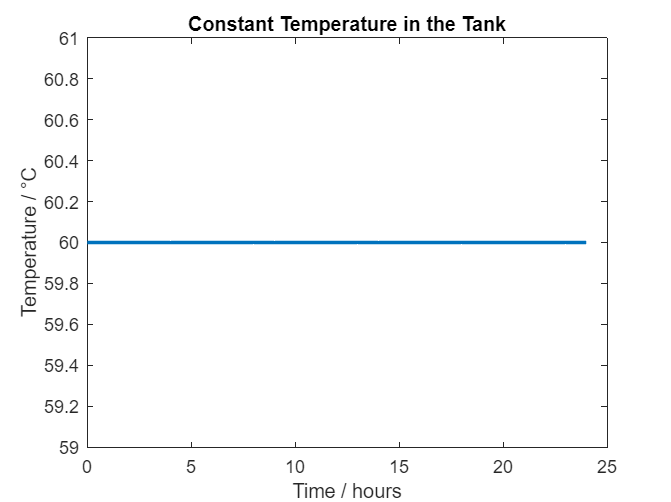



t = 0:24; 
plot(t, T_target - 273.15 * ones(size(t)), 'LineWidth', 2)
xlabel('Time / hours')
ylabel('Temperature / °C')
title('Constant Temperature in the Tank')
ylim([59 61])  

Rinse Tank Energy Balance Calculations

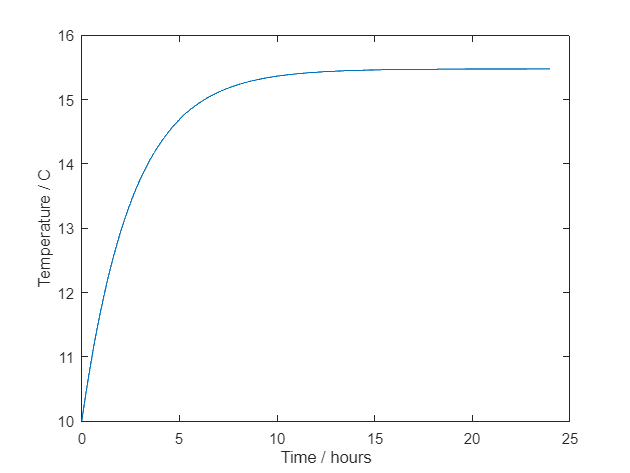

clc
clear all

L = 4; %m
W = 2.5;
tri_d = 0.6; % m
cub_d = 0.4 ;% m
L_tri = sqrt((W/2)^2 + tri_d^2); % m
T_ref = 283.15; %K reference and assumed surroundings temp
T60 = 333.15;
T_wat = 283.15;
rho_bulk = 400; %kg/m3
rho_w = 1000;

%assume plasstic fully covers surface of water. 10mins residence time
SA_surf = 4*2.5;
V_tank =  0.5*W*tri_d*L + W*cub_d*L;
SA_tank = L * cub_d * 2 + W * cub_d * 2 + 2 * L_tri * L; % Surface area of tank walls in contct with water
mdot_plastic = 2.3; %kg/hr
Vdot_plastic = (1000*55.221/24)/rho_bulk; % m³/hr
SA_plas = (Vdot_plastic/6)/.1; %.1 = depth of plastic
V_water = 0.5*W*tri_d*L + W*(cub_d-0.2)*L; % Volume of water in the tank if levele is 0.2m below top of tank
Vdot_water = 1.5; %m3/hr
Vdot_hot = 0.209;

U_HD = 0.5; %W/mK
U_LD = 0.33;
U_PP = .2;
U_avg = .3*.5 + .3*.33 + .4*.2;
U_ss = 16;

cp_water = 4200; %J/kgK
cp_HD = 1900;
cp_LD = 2100;
cp_PP = 1800;
cp_avg = .3*cp_HD + .3*cp_LD + .4*cp_PP;

Q_plastic = 157.71;

dt = 60;
T(1) = 283.15;
t(1) = 0;


for i = 2:((3600*24)/dt)+1
    t(i) = (i-1)*dt;
    Q_steel = U_ss*SA_tank*(T(i-1)-T_ref);
    Q_whin = (Vdot_hot/3600) *rho_w*cp_water*(T60-T_ref) + Q_plastic; %water from hot tank
    Q_wcin = (Vdot_water/3600) *rho_w*cp_water*(T_wat-T_ref);
    Q_wout = (Vdot_water/3600) * rho_w*cp_water*(T(i-1)-T_ref);
    Q_wout2 = (Vdot_hot/3600) *rho_w*cp_water*(T(i-1)-T_ref);%water to dryer 
    dTdt = (Q_whin + Q_wcin - Q_wout - Q_wout2 - Q_steel)/(V_water*rho_w*cp_water);
    T(i) = T(i-1) + dt*dTdt;
end

plot(t/(3600),T-273.15)
%yticks(59:0.25:61)
%ylim([59 61])
xlabel("Time / hours")
ylabel("Temperature / C")

fprintf('Steady state temperature of water in tank 2: %.2f°C\n', T(end)-273.15);

Steady state temperature of water in tank 2: 15.48°C


Checking hot wash calculation

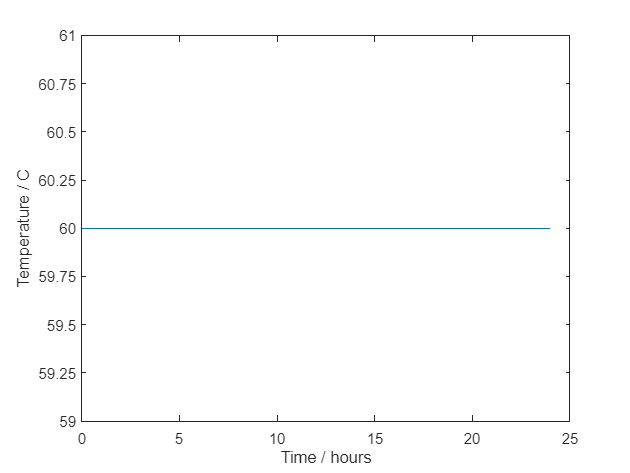

clc
clear all

L = 4; %m
W = 2.5;
tri_d = 0.6; % m
cub_d = 0.4 ;% m
L_tri = sqrt((W/2)^2 + tri_d^2); % m
T_ref = 283.15; %K reference and assumed surroundings temp
T60 = 333.15;
rho_bulk = 400; %kg/m3
rho_w = 998;

%assume plasstic fully covers surface of water. 10mins residence time
SA_surf = 4*2.5;
V_tank =  0.5*W*tri_d*L + W*cub_d*L;
SA_tank = L * cub_d * 2 + W * cub_d * 2 + 2 * L_tri * L; % Surface area of tank walls in contct with water
mdot_plastic = 2.3; %kg/hr
Vdot_plastic = (1000*55.221/24)/rho_bulk; % m³/hr
SA_plas = (Vdot_plastic/6)/.1; %.1 = depth of plastic
V_water = 0.5*W*tri_d*L + W*(cub_d-0.2)*L; % Volume of water in the tank if levele is 0.2m below top of tank
Vdot_water = 2.5; %m3/hr
Vdotg = 0.1;

U_HD = 0.5; %W/mK
U_LD = 0.33;
U_PP = .2;
U_avg = .3*.5 + .3*.33 + .4*.2;
U_ss = 16;

cp_water = 4200; %J/kgK


Q_steel = U_ss*SA_tank*(T60-T_ref);
Q_plastic = U_avg*SA_plas*(T60-T_ref);
% Q_sstank = V_water*rho_w*cp_water*(T60-T_ref);
% fprintf('energy of water in tank = %.2f W \n', Q_sstank);
Q_gran = (Vdotg/3600)*rho_w*cp_water*(T60 - T_ref);
Q_win = (Vdot_water)/3600 *rho_w*cp_water*(273.15+66.53-T_ref); %in stream is 64.53C to maintain 60C in tank



dt = 60;
T(1) = 333.15;
t(1) = 0;


for i = 2:((3600*24)/dt)+1
    t(i) = (i-1)*dt;
    dTdt = (Q_win - Q_gran - Q_plastic - Q_steel - (Vdot_water/3600) * rho_w*cp_water*(T(i-1)-T_ref))/(V_water*rho_w*cp_water);
    T(i) = T(i-1) + dt*dTdt;
end

plot(t/(3600),T-273.15)
yticks(59:0.25:61)
ylim([59 61])
xlabel("Time / hours")
ylabel("Temperature / C")